cmenv;

CarMaker directory: C:/IPG/carmaker/win64-10.1
addpath C:\IPG\carmaker\win64-10.1\Matlab
addpath C:\IPG\carmaker\win64-10.1\Matlab\R2020a
addpath C:\IPG\carmaker\win64-10.1\CM4SL
addpath C:\IPG\carmaker\win64-10.1\CM4SL\R2020a
Initialize CarMaker for Simulink.
Done.


file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 0.erg'

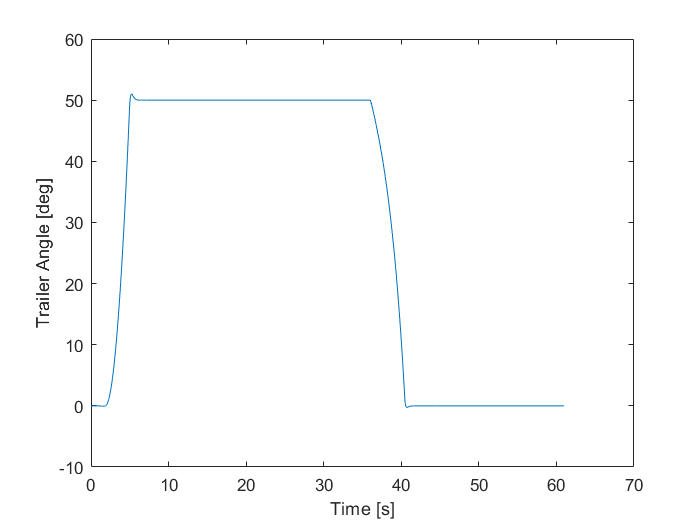

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 1.erg'

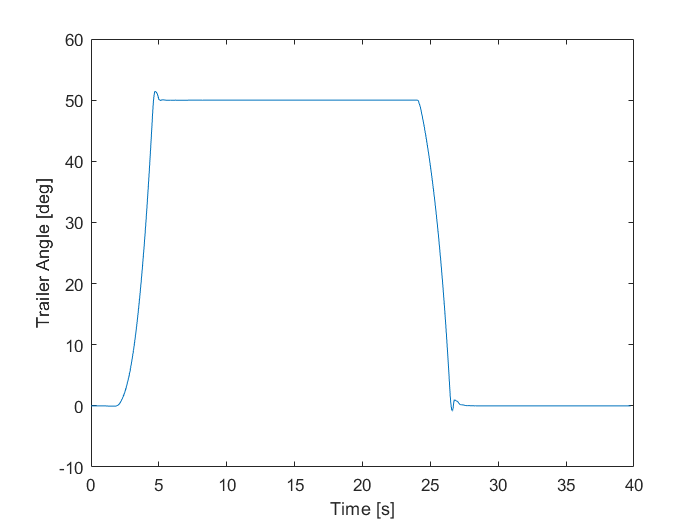

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 2.erg'

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 3.erg'

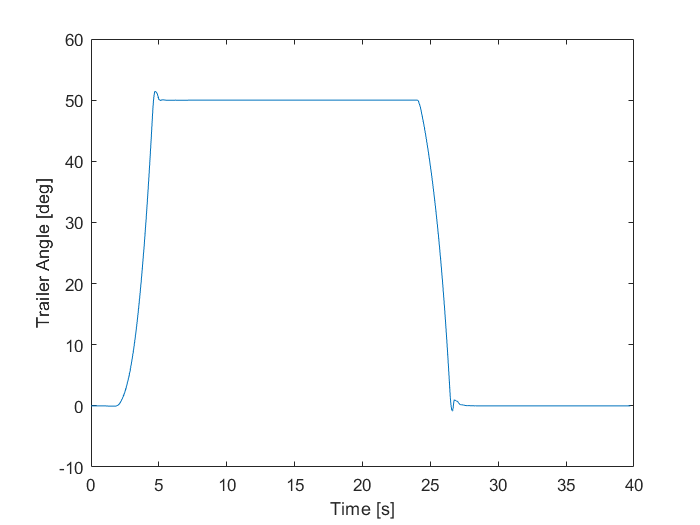

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 4.erg'

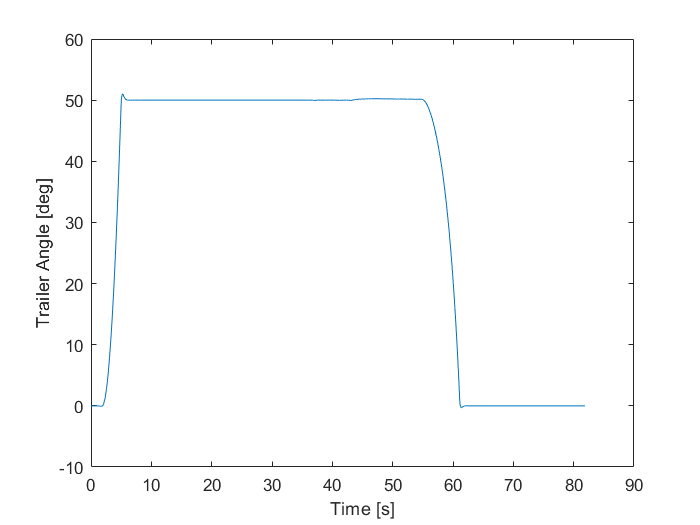

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 5.erg'

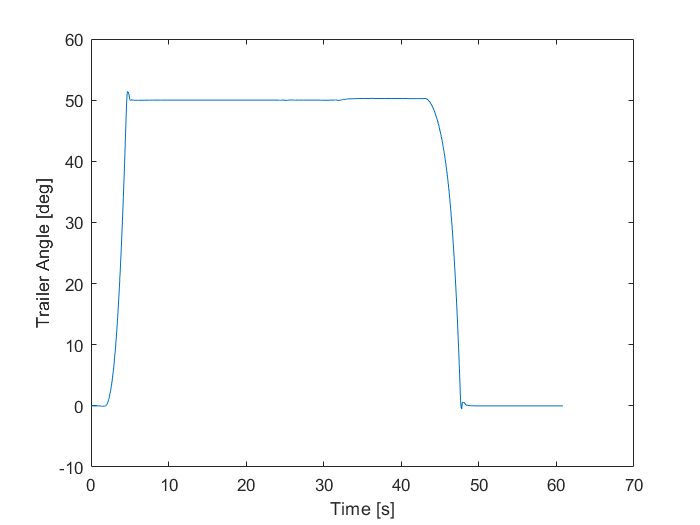

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 6.erg'

file = 'C:\Users\leo_g\Documents\SocioFormador\CarMaker\SimOutput\challenge\returnLine\Variation 7.erg'

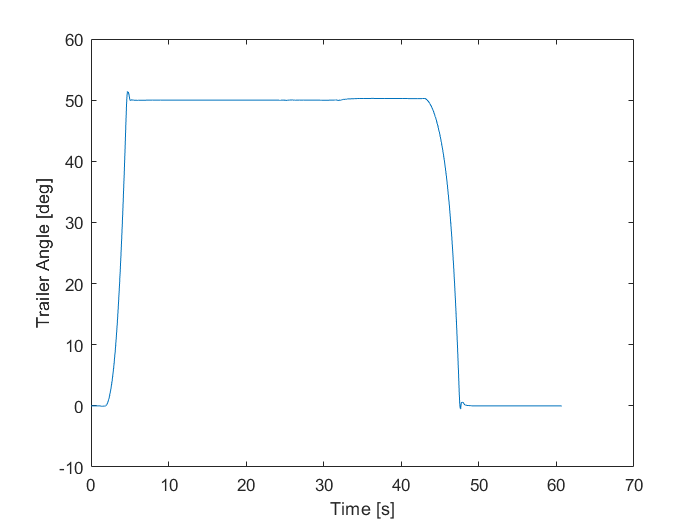

%El numero que indicara que Validacion leer
numero = 0;
%Guardamos los valores en vectores
tp_vector = [];
mp_vector = [];
ts_vector = [];
tiem_cer_vec = [];
for j = 0:1:7
    %Obtenemos la direccion de cada archivo 
    archivo = ['Variation' ' ' num2str(numero)];
    estado_mayor = false;
    estado_cero = false;
    %Leemos cada archivo
    file = ([pwd,'\','returnLine\',archivo,'.erg'])
    CM = cmread(file);
    %Obtenemos datos y ploteamos la graficas de cada prueba
    Time_s = CM.Time.data';
    TrailerAngle_deg = (CM.Tr_Hitch_dr_0_z.data)*(180/pi);
    plot(Time_s,TrailerAngle_deg)
    xlabel('Time [s]')
    ylabel('Trailer Angle [deg]')
    figure
    
    lugar = 0;
    inicio = 0;
    estado = true;
    estado_2 = true;
    for i = TrailerAngle_deg
        lugar = lugar + 1;
        
        if estado_mayor == false
            if i > 0.1 && estado == true
                %Obtenemos el timepo de inicio del cambio de grado cero al deseado.
                inicio = Time_s(lugar);
                estado = false;
            end
            if i >= 50 
                if TrailerAngle_deg(lugar + 1) < i
                    %Obtenemos el maximp mp y el tp
                    mp_1 = i;
                    tp = Time_s(lugar) - inicio;
                    estado_mayor = true;
                end
            end
        end
        %Detectamos cuando va del angulo deseado anterior a
        %cero nuevamente
        if estado_mayor == true
            if i < 49.5 && estado_2 == true
                inicio_menor = Time_s(lugar);
                estado_2 = false;
            end
            if i < 0.1 && estado_cero == false
                %Obtenemos cuando llega a cero nuevamente
                tiempo_cero = Time_s(lugar) - inicio_menor;
                estado_cero = true;
                tiem_cer_vec(end + 1) = tiempo_cero;
            end
        end
    end
    %Obtenemos factpres deseados como mp, tp, wn y ts
    mp = ((mp_1 - 50)/50);
    factor = (((log(mp))^2)/((log(mp))^2+pi^2))^0.5;
    Wn = pi/(tp*((1-(factor)^2)^0.5));
    ts = 4/(factor*Wn);
    numero = numero + 1;
    %Lo agregamos al vector para guardarlo
    mp_vector(end + 1) = mp;
    tp_vector(end + 1) = tp;
    ts_vector(end + 1) = ts;
end

%Hacemos el análisis estadístico de los vectores.
tp_vector

tp_vector =     3.2600    2.7400    3.2600    2.7400    3.2600    2.7400    3.2600    2.7400


media_tp = mean(tp_vector);
moda_tp = mode(tp_vector);
median_tp = median(tp_vector);
std_tp = std(tp_vector);
var_tp = var(tp_vector);
fprintf("Media tp: %d\t", media_tp);

Media tp: 3.000000e+00	

fprintf(",varianza tp: %d\t", var_tp);

,varianza tp: 7.725714e-02	

fprintf(",desviación std tp: %d\n", std_tp);

,desviación std tp: 2.779517e-01



mp_vector

mp_vector =     0.0208    0.0287    0.0208    0.0287    0.0208    0.0287    0.0208    0.0287


media_mp = mean(mp_vector);
moda_mp = mode(mp_vector);
median_mp = median(mp_vector);
std_mp = std(mp_vector);
var_mp = var(mp_vector);
fprintf("Media mp: %d\t", media_mp);

Media mp: 2.473707e-02	

fprintf(",varianza mp: %d\t", var_mp);

,varianza mp: 1.796309e-05	

fprintf(",desviación std mp: %d\n", std_mp);

,desviación std mp: 4.238289e-03



ts_vector

ts_vector =     3.3659    3.0863    3.3659    3.0869    3.3659    3.0863    3.3659    3.0869


media_ts = mean(ts_vector);
moda_ts = mode(ts_vector);
median_ts = median(ts_vector);
std_ts = std(ts_vector);
var_ts = var(ts_vector);
fprintf("Media ts: %d\t", media_ts);

Media ts: 3.226274e+00	

fprintf(",varianza ts: %d\t", var_ts);

,varianza ts: 2.228742e-02	

fprintf(",desviación std ts: %d\n", std_ts);

,desviación std ts: 1.492897e-01



tiem_cer_vec

tiem_cer_vec =     4.4300    2.3500    4.4300    2.3500    5.6500    3.9100    5.6500    3.9100


media_tiem_cer = mean(tiem_cer_vec);
moda_tiem_cer = mode(tiem_cer_vec);
median_tiem_cer = median(tiem_cer_vec);
std_tiem_cer = std(tiem_cer_vec);
var_tiem_cer = var(tiem_cer_vec);
fprintf("Media regreso a cero: %d\t", media_ts);

Media regreso a cero: 3.226274e+00	

fprintf(",varianza regreso a cero: %d\t", var_ts);

,varianza regreso a cero: 2.228742e-02	

fprintf(",desviación std regreso a cero: %d\n", std_ts);

,desviación std regreso a cero: 1.492897e-01
